# Data Understanding & Preparation

Describe the dataset, explain preprocessing steps, and provide visualizations.

Key components:

- Dataset source and description (size, features, target variable)

- Data cleaning (handling missing values, duplicates, outliers)

- Preprocessing (dimensionality reduction, transformations)

- Data splitting (training, validation, test sets)

- Visualizations (histograms, scatter plots, correlation matrices, etc.)

## Describe the Dataset

The data is in monthly format and it has been acquired from Statfin and Kela. The observations are from January 2019 to March 2025. In total, there are eight Excel spreadsheets, of which one contains the target variable.

The Excel spreadsheets each contain a time column and a feature column The target variable spreadsheet contains both absolute and relative information, of which only absolute values are used.

Independent variables (features, X):

- kela_housing_benefits.xlsx

- kela_housing_b_per_person.xlsx

- kela_unemployment_benefits.xlsx

- kela_unemployment_b_per_person.xlsx

- statfin_relative_unemployment.xlsx

- statfin_consumer_price_index.xlsx

- statfin_consumer_confidence_indicator.xlsx

Dependent variable (target, Y):

- kela_social_assistance.xlsx

In addition, two date columns (year and month) and one dummy variable (government cuts) are created in the code below. The final cleaned dataset is briefly described at the end of the *Data Visualization* section.

## Preprocessing Steps

% This snippet of code creates a unified data table, as well as predictor matrix X and
% target variable Y.

% Set rng to default:
rng('default');

% Import all the data as tables:
kela1 = readtable("kela_housing_benefits.xlsx");

kela2 = readtable("kela_housing_b_per_person.xlsx");

kela3 = readtable("kela_unemployment_benefits.xlsx");

kela4 = readtable("kela_unemployment_b_per_person.xlsx");


statfin1 = readtable("statfin_relative_unemployment.xlsx");

statfin2 = readtable("statfin_consumer_price_index.xlsx");

statfin3 = readtable("statfin_consumer_confidence_indicator.xlsx");


kelaY = readtable("kela_social_assistance.xlsx");


% Remove empty spaces from kela3, kela4 and kelaY and the last row from
% statfin3 to make the dimensions of the data consistent:
kela3(76:end,:) = [];
kela4(76:end,:) = [];
statfin3(end,:) = [];
kelaY(76:end,:) = [];

% The data from Kela is ordered in descending order, flip it the other way
% round to match the data from Statfin:
kela1 = flip(kela1);
kela2 = flip(kela2);
kela3 = flip(kela3);
kela4 = flip(kela4);
kelaY = flip(kelaY);

% Create YY and MM columns by using one of the tables:
[YY,MM] = ymd(datetime(kela1.Time,"InputFormat","uuuu-MM"));

% Create a single datetime column to be used in visualizations later on:
time_axis = datetime(kela1.Time,"InputFormat","uuuu-MM","Format","MM/uuuu");

% Remove columns not needed, such as dates, from all the tables and convert them to arrays:
kela1 = table2array(kela1(:,3));
kela2 = table2array(kela2(:,3));
kela3 = table2array(kela3(:,3));
kela4 = table2array(kela4(:,3));
statfin1 = table2array(statfin1(:,2));
statfin2 = table2array(statfin2(:,2));
statfin3 = table2array(statfin3(:,2));
kelaY = table2array(kelaY(:,2));

% Create a dummy variable for the government cuts (0 before cuts, 1 after
% cuts):
gov_cut = zeros(length(YY),1);
gov_cut(64:end,:) = 1; % From 2024-4 onwards

% Transform inflation to start from 100:
statfin2 = statfin2 / statfin2(1) * 100;

% Transform the amount of housing and unemployment benefits paid per person to
% indices for better visualization, where 2024-4 = 100:
kela2 = kela2 / kela2(64) * 100; % Housing benefits paid per person index
kela4 = kela4 / kela4(64) * 100; % Unemployment benefits paid per person index

% Create predictor dataset X:
X = [YY, MM, gov_cut, statfin1, statfin2, statfin3, kela1, kela2, kela3, kela4];

% Create target variable Y:
Y = kelaY;

% Create a datatable with column names for better data visualization:
var_names = {'YY','MM','gov_cut','unemployment','CPI','CCI','Housing benefits EUR',...
    'Housing benefits IDX','Unemployment benefits EUR','Unemployment benefits IDX',...
    'Social assistance recipients'};
data_table = array2table([X,Y],"VariableNames",var_names);

The predictor dataset X contains 10 variables and 75 instances/observations. The target variably Y is the amount of social assistance recipients with 75 instances. The data is ordered in ascending order according to YY-MM (oldest observation first).

The number of observations is quite low which will most likely affect the results.

% This part of the code inspects the created datasets (X, Y,
% data_table) and checks if further preprocessing is needed.

% Display a summary of the data
disp('Original data:')

Original data:


summary(data_table)


data_table: 75×11 table

Variables:

    YY: double
    MM: double
    gov_cut: double
    unemployment: double
    CPI: double
    CCI: double
    Housing benefits EUR: double
    Housing benefits IDX: double
    Unemployment benefits EUR: double
    Unemployment benefits IDX: double
    Social assistance recipients: double

Statistics for applicable variables:

                                  NumMissing         Min              Median             Max               Mean              Std      

    YY                                0                 2019              2022              2025            2021.6            1.8206  
    MM                        <


% Convert gov_cut to categorical for both data_table and X:
data_table.gov_cut = categorical(data_table.gov_cut);
X(:,3) = categorical(X(:,3));

% Check the data:
disp('Fixed data:')

Fixed data:


summary(data_table)


data_table: 75×11 table

Variables:

    YY: double
    MM: double
    gov_cut: categorical (2 categories)
    unemployment: double
    CPI: double
    CCI: double
    Housing benefits EUR: double
    Housing benefits IDX: double
    Unemployment benefits EUR: double
    Unemployment benefits IDX: double
    Social assistance recipients: double

Statistics for applicable variables:

                                  Num

The data is now complete with correct types and no missing information.

% This part splits the data into training, testing and validation sets.
% Validation of models uses K-fold cross-validation, since the dataset is
% quite small.

% Create a partition for testing (30%) and training (70%):
cv1 = cvpartition(length(Y),'HoldOut',0.3);
X_train = X(training(cv1),:);
Y_train = Y(training(cv1),:);
X_test = X(test(cv1),:);
Y_test = Y(test(cv1),:);

% Create a 4-fold cross-validation partition:
cv_kfold = cvpartition(length(Y_train),'KFold',4);

The models are trained and compared using the cv_kfold variable as the number of observations is low. Validation dataset should not be needed with kfold, as lasso, ridge and PC regressions can use  *'CV', cv_kfold* in their parameters.

% Clear unused variables
clear kela1 kela2 kela3 kela4 kelaY statfin1 statfin2 statfin3 var_names MM YY gov_cut cv1

## Data Visualization

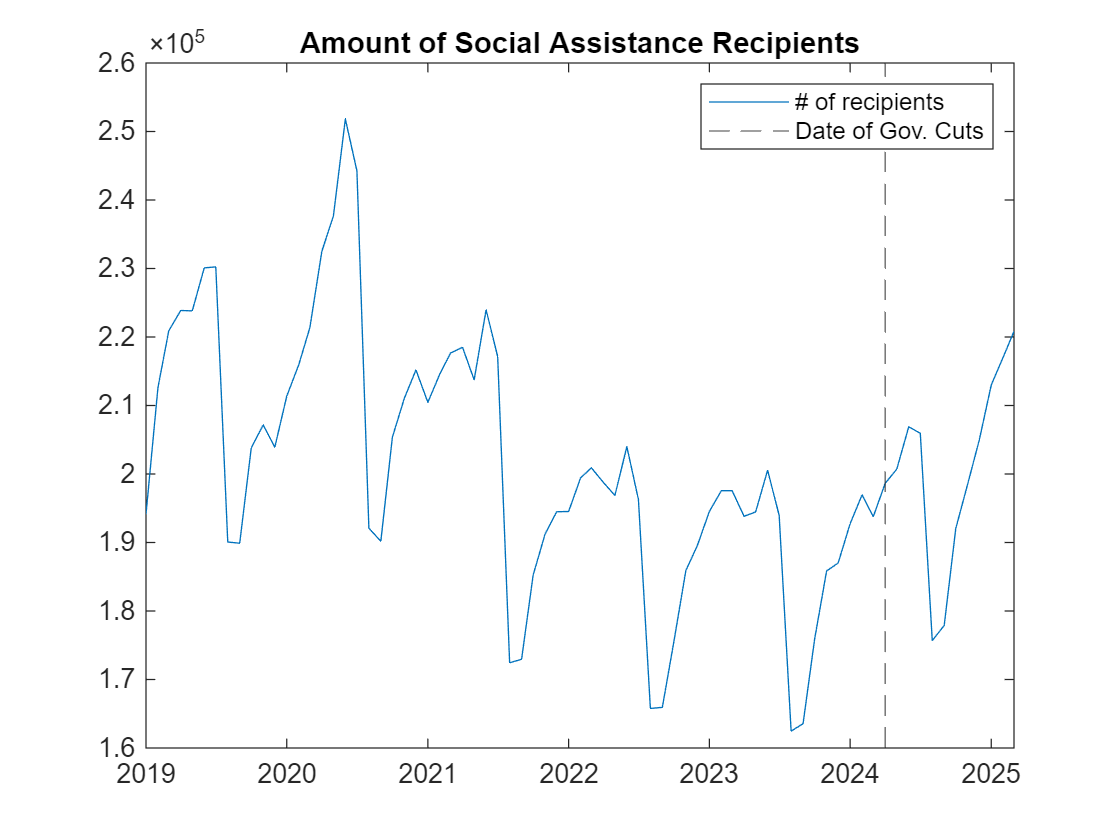

% This part visualizes various aspects of the data.

% Check the amount of social assistance recipients:
figure;
plot(time_axis,Y);
xline(time_axis(64),'--');
title("Amount of Social Assistance Recipients")
legend ('# of recipients','Date of Gov. Cuts');

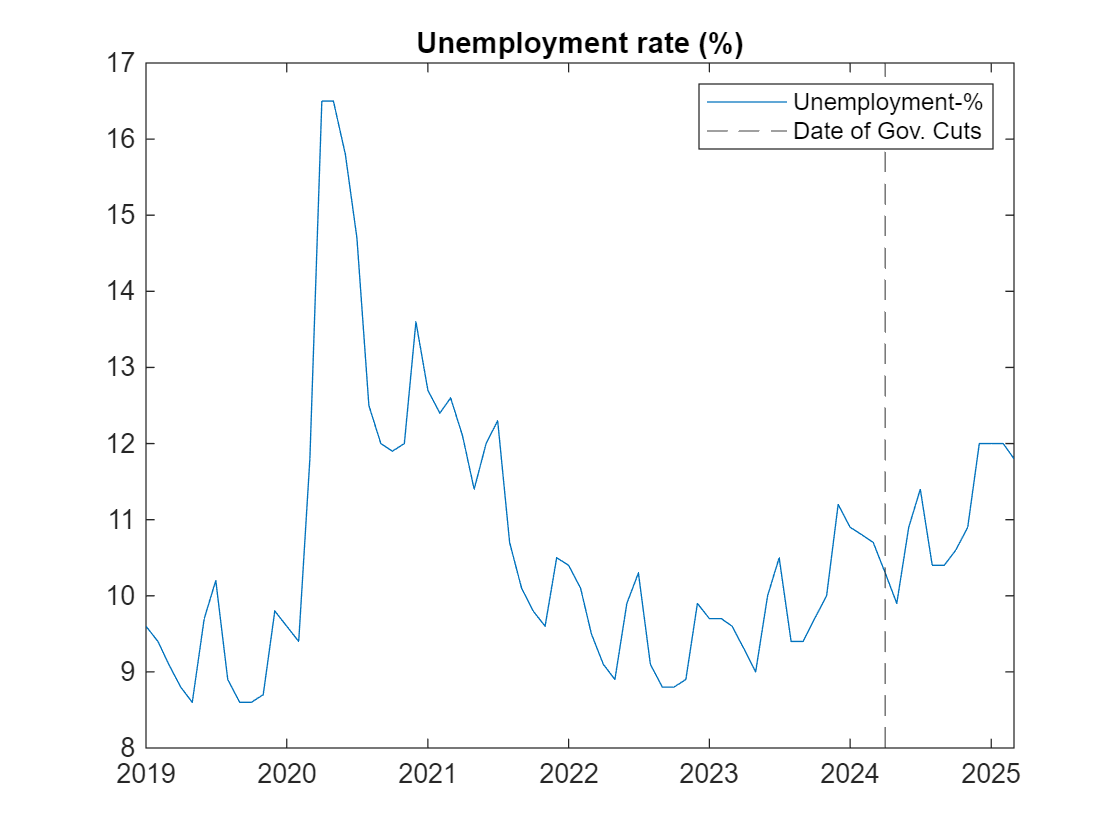


% Plot unemployment rate:
figure;
plot(time_axis,data_table.unemployment);
xline(time_axis(64),'--');
title("Unemployment rate (%)")
legend ('Unemployment-%','Date of Gov. Cuts');

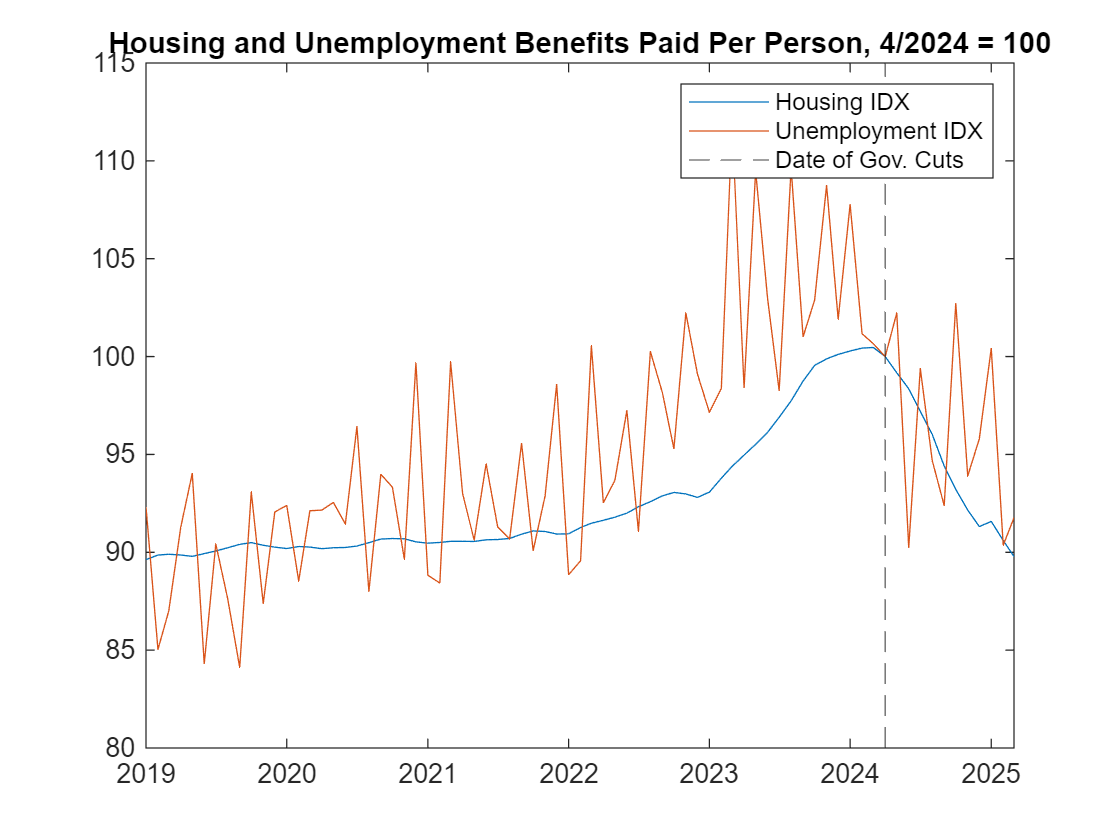


% Visualize the housing and unemployment benefit indices as well as the
% date of government cut:
figure;
plot(time_axis,data_table.("Housing benefits IDX"));
hold on;
plot(time_axis,data_table.("Unemployment benefits IDX"));
xline(time_axis(64),'--');
legend ('Housing IDX','Unemployment IDX','Date of Gov. Cuts');
title("Housing and Unemployment Benefits Paid Per Person, 4/2024 = 100")
hold off;

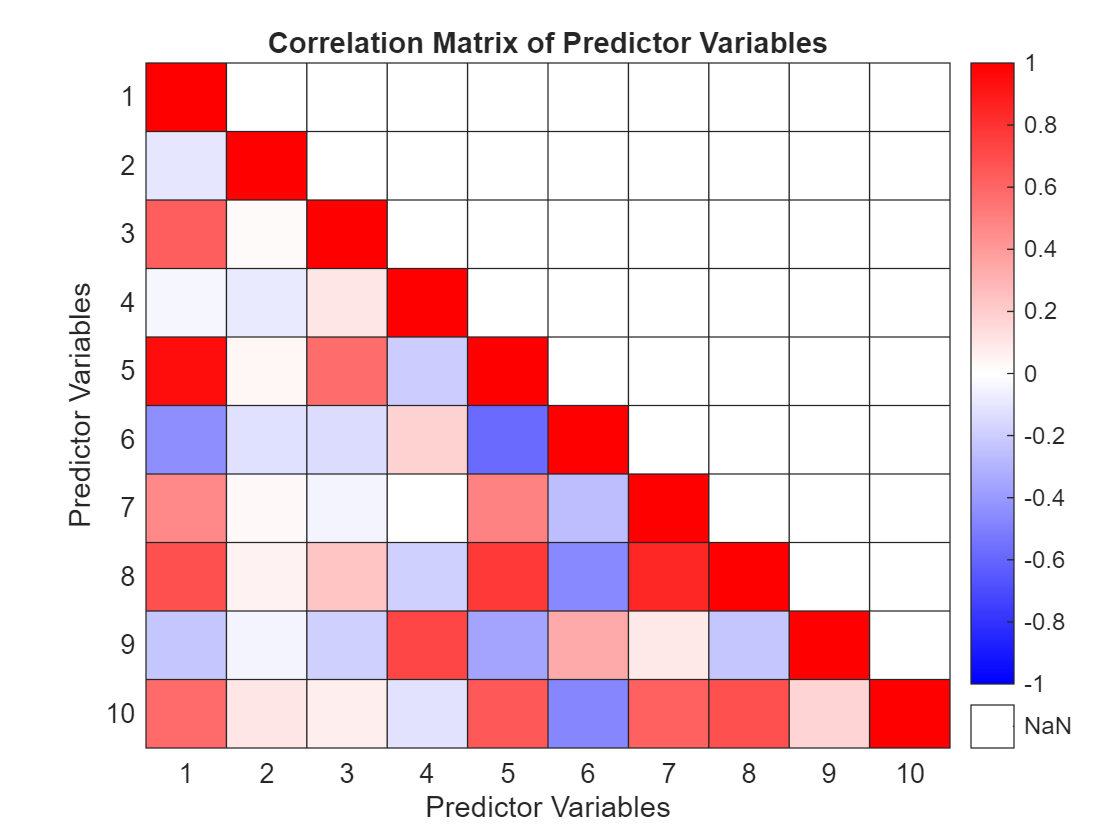


% Check correlations between the predictor variables:
C = corr(X);
isupper = logical(triu(ones(size(C)),1));
C(isupper) = NaN;
figure;
% Define a blue-red colormap
cmap = [linspace(0,1,128)', linspace(0,1,128)', ones(128,1); % Blue to white
        ones(128,1), linspace(1,0,128)', linspace(1,0,128)']; % White to red

h = heatmap(C, 'MissingDataColor', 'w', 'Colormap', cmap,'ColorLimits', [-1, 1]);
h.Title = 'Correlation Matrix of Predictor Variables';
h.XLabel = 'Predictor Variables';
h.YLabel = 'Predictor Variables';
h.FontSize = 10;

Summary of predictor matrix X in order:

- Year

- Month

- Government cut (categorical: 1 no cuts, 2 cuts in effect (4/2024 onwards))

- Unemployment

- CPI (inflation)

- CCI (consumer confidence)

- Housing benefits paid (monthly total, EUR)

- Housing benefits paid per person (index, 4/2024 = 100) 

- Unemployment benefits paid (monthly, EUR)

- Unemployment benefits paid per person (index, 4/2024 = 100)

The visualizations show that the target variable Y (amount of social assistance recipients) is cyclical. There is also both positive and negative correlation present within the predictor variables.

% Clear unused variables:
clear C cmap h isupper time_axis

# Model Development

Original data:

- **X**: predictor matrix (9 continuous variables, 1 categorical variable, 75 observations) in array format.

- **Y**: target variable (1 continuous variable, 75 observations) in array format.

- **data_table**: unified dataset (both x and y) in table format.

Split data:

- **X_train**: predictor training set (53 observations).

- **Y_train**: target training set (53 observations).

- **X_test**: predictor test set (22 observations).

- **Y_test**: target test set (22 observations).

- **cv_kfold**: 4-fold cross-validation partition object to be used in model training, separate validation dataset should not be needed with the cross-validation regression models.

## LINEAR REGRESSION 

Fitting linear regression model

% Linear model with column 3 as a categorical variable:
linear_mdl=fitlm(X_train,Y_train,'linear','CategoricalVars',3);

Evaluating model performance using test data

% One linear model only, so it is also the final one:
Ypred_linear = predict(linear_mdl, X_test);
MSE_linear = immse(Y_test,Ypred_linear)

MSE_linear =    1.5871e+08


## LASSO REGRESSION WITH K-FOLD CROSS VALIDATION

Testing with 100 different lambda values to find the best regularization parameter. 

% [coefficients, additional information]
[b_lasso, fitinfo_lasso] = lasso(X_train,Y_train,'CV',cv_kfold,'NumLambda',100);

Plot:

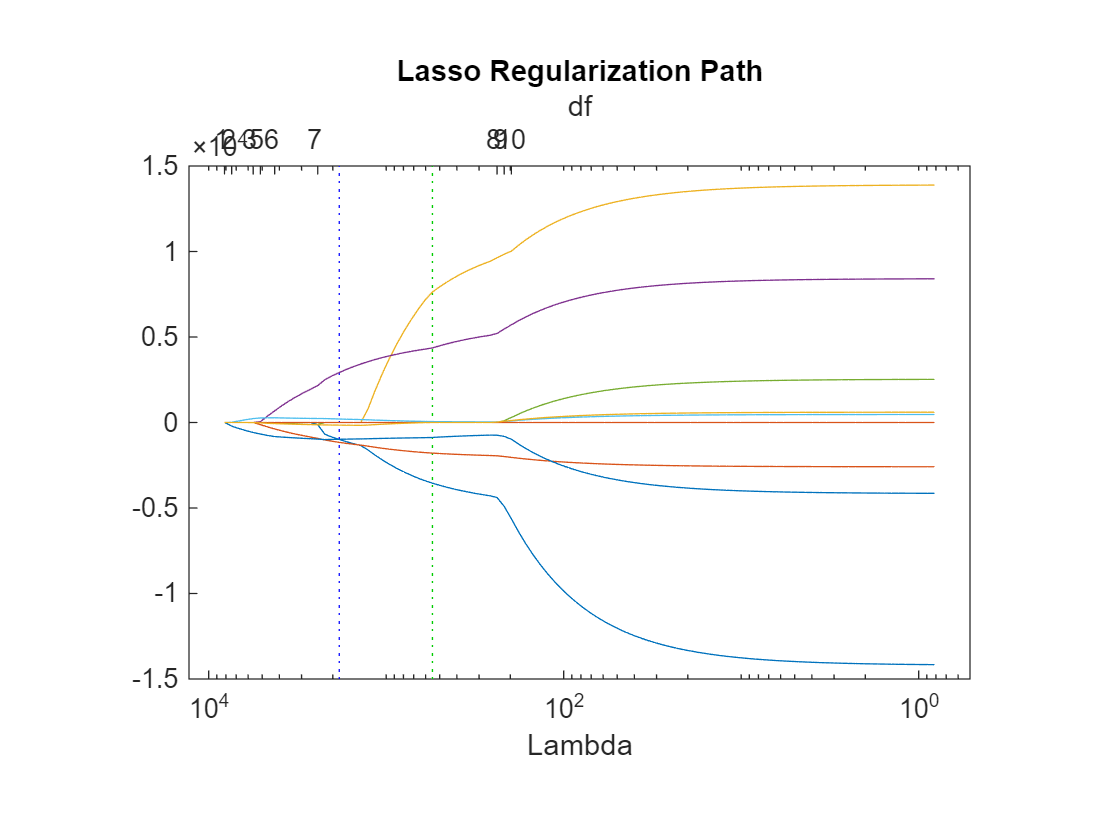

lassoPlot(b_lasso,fitinfo_lasso,'PlotType','Lambda','XScale','log');
title('Lasso Regularization Path');

Examing the Cross-Validated MSE

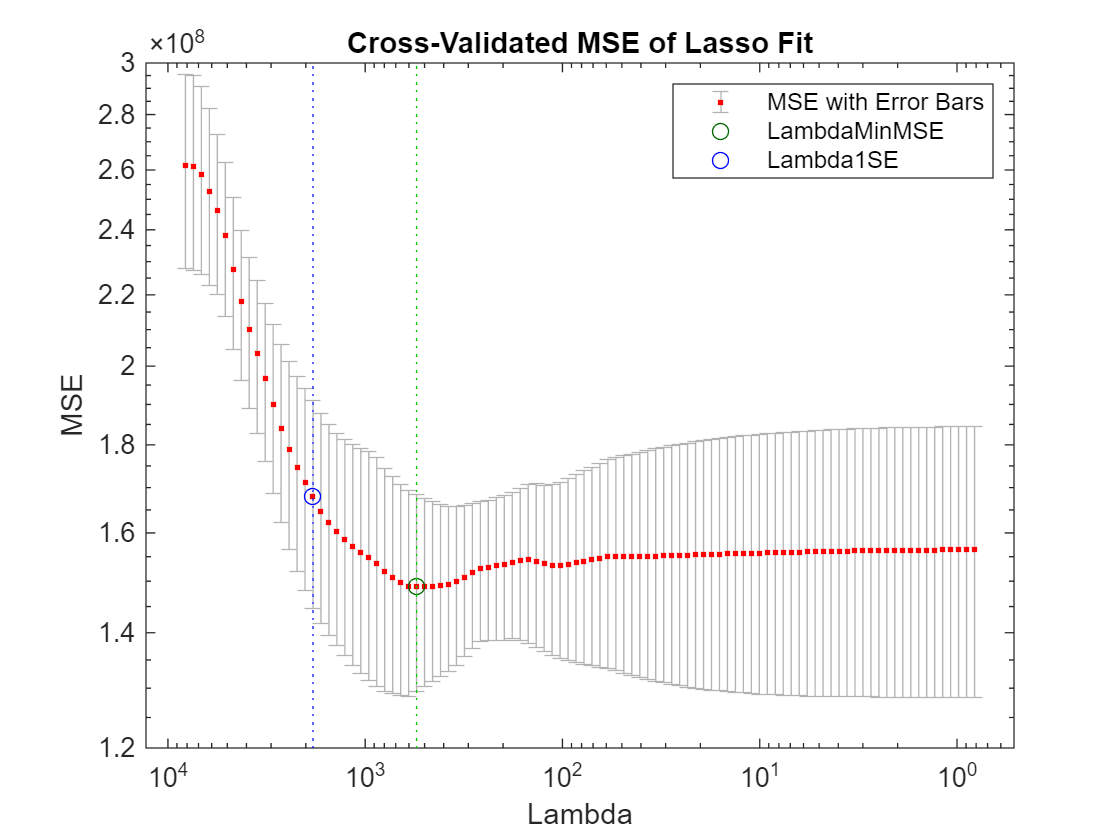

lassoPlot(b_lasso,fitinfo_lasso,'PlotType', 'CV','XScale','log');
set(gca,'YScale','log');
legend('show')

Exploring parameters in corresponde of Lambda1SE and LambdaMinMSE

% Optimal lambda values:
Lambda1SE_lasso= fitinfo_lasso.Lambda1SE

Lambda1SE_lasso =        1839.5


LambdaMinMSE_lasso= fitinfo_lasso.LambdaMinMSE

LambdaMinMSE_lasso =        548.83


% Their indices:
lambdaindex_lasso_1SE= fitinfo_lasso.Index1SE;
lambdaindex_lasso_Min = fitinfo_lasso.IndexMinMSE;
% MSEs corresponding to the optimal lambdas:
mse_lasso_1SE=fitinfo_lasso.MSE(lambdaindex_lasso_1SE)

mse_lasso_1SE =    1.6792e+08


mse_lasso_Min = fitinfo_lasso.MSE(lambdaindex_lasso_Min)

mse_lasso_Min =    1.4893e+08


% Number of non-zero coefficients:
num_coeffs_lasso_Lambda1SE = fitinfo_lasso.DF(lambdaindex_lasso_1SE)

num_coeffs_lasso_Lambda1SE =      6


num_coeffs_lasso_LambdaMinMSE=fitinfo_lasso.DF(lambdaindex_lasso_Min)

num_coeffs_lasso_LambdaMinMSE =      7


% Actual coefficients:
b_lasso_1SE=b_lasso(:,lambdaindex_lasso_1SE);
b_lasso_MinMse=b_lasso(:,lambdaindex_lasso_Min);

Retraining the model with LambdaMinMSE

[Bfinal_lasso,fitInfofinal_lasso] = lasso(X_train,Y_train,'Lambda',LambdaMinMSE_lasso);

Evaluating the final lasso model on Test data

test_predictions_lasso = fitInfofinal_lasso.Intercept + X_test*Bfinal_lasso;
MSEtest_lasso = immse(Y_test,test_predictions_lasso)

MSEtest_lasso =    1.6119e+08


% Clear unused variables
clear b_lasso fitinfo_lasso lambdaindex_lasso_1SE lambdaindex_lasso_Min

## RIDGE REGRESSION WITH K-FOLD CROSS-VALIDATION

Lasso function tests 100 different lambda values by default. 

% [coefficients, additional information]
[b_ridge, fitinfo_ridge] = lasso(X_train,Y_train,'CV',cv_kfold,"Alpha",0.001,'NumLambda',100);

Plot:

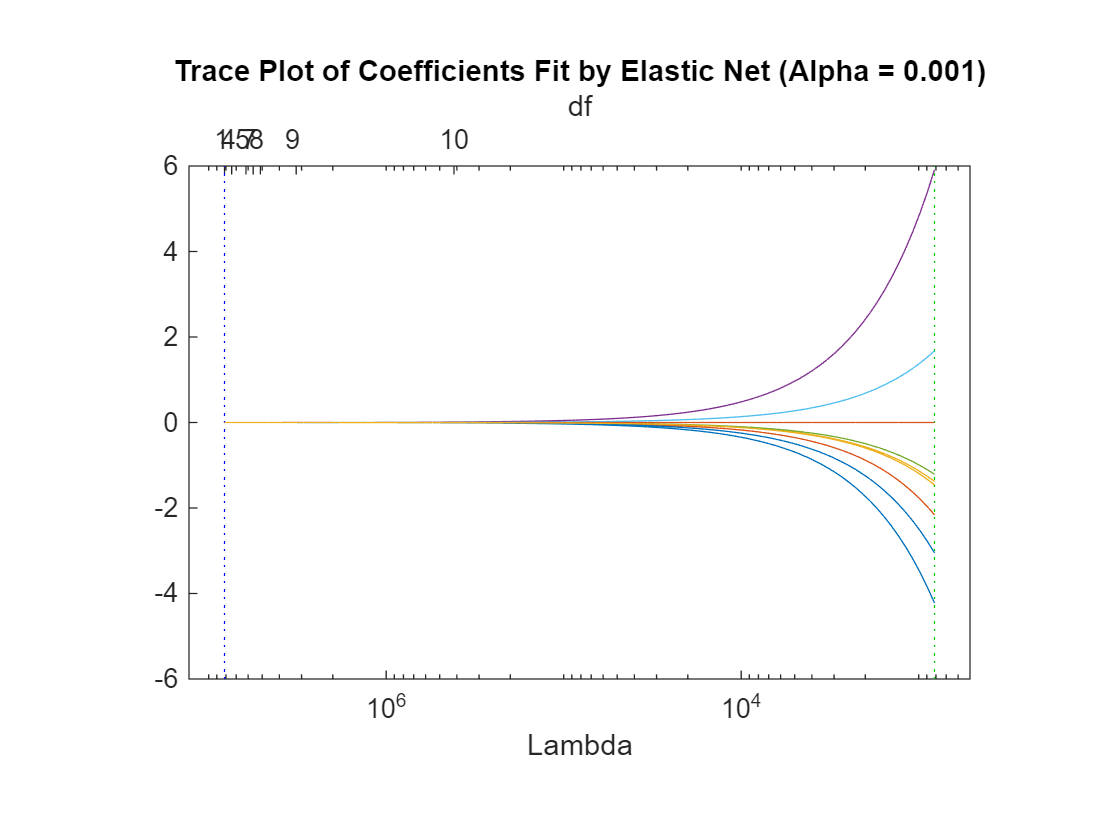

lassoPlot(b_ridge, fitinfo_ridge,'PlotType','Lambda','XScale','log');

Examing the Cross-Valitated MSE

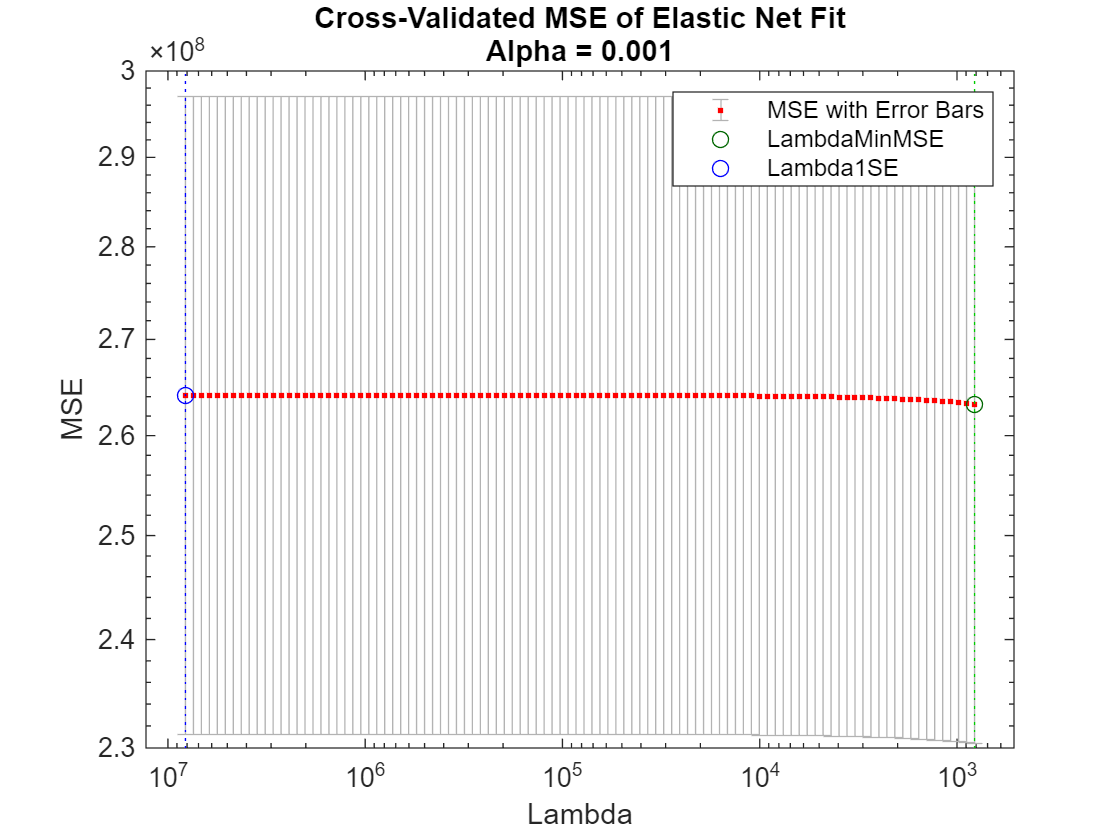

lassoPlot(b_ridge, fitinfo_ridge,'PlotType', 'CV','XScale','log');
set(gca,'YScale','log');
legend('show')

Exploring parameters in correspondence of Lambda1SE and LambdaMinMSE

% Optimal lambdas:
Lambda1SE_ridge = fitinfo_ridge.Lambda1SE

Lambda1SE_ridge =    8.1499e+06


LambdaMinMSE_ridge = fitinfo_ridge.LambdaMinMSE

LambdaMinMSE_ridge =        814.99


% Their indices:
lambdaindex_ridge_1SE = fitinfo_ridge.Index1SE;
lambdaindex_ridge_Min = fitinfo_ridge.IndexMinMSE;
% MSEs with the optimal lambdas:
mse_ridge_1SE = fitinfo_ridge.MSE(lambdaindex_ridge_1SE)

mse_ridge_1SE =    2.6415e+08


mse_ridge_Min = fitinfo_ridge.MSE(lambdaindex_ridge_Min)

mse_ridge_Min =    2.6324e+08


% Number of non-zero coefficients with optimal lambdas:
num_coeffs_ridge_Lambda1SE = fitinfo_ridge.DF(lambdaindex_ridge_1SE)

num_coeffs_ridge_Lambda1SE =      1


num_coeffs_ridge_LambdaMinMSE = fitinfo_ridge.DF(lambdaindex_ridge_Min)

num_coeffs_ridge_LambdaMinMSE =     10


% Actual coefficients:
b_ridge_1SE=b_ridge(:,lambdaindex_ridge_1SE);
b_ridge_MinMse=b_ridge(:,lambdaindex_ridge_Min);

Lambda1SE keeps only one coefficient, MinMSE keeps all 10!

Retraining the model with LambdaMinMSE

[Bfinal_ridge, fitInfofinal_ridge] = lasso(X_train, Y_train, 'Lambda',LambdaMinMSE_ridge, 'Alpha', 0.001);

Evaluating the final ridge model on test data

test_predictions_ridge = fitInfofinal_ridge.Intercept + X_test * Bfinal_ridge;
MSEtest_ridge = immse(Y_test, test_predictions_ridge)

MSEtest_ridge =    5.3356e+08


% Clear unused variables
clear b_ridge fitinfo_ridge lambdaindex_ridge_1SE lambdaindex_ridge_Min

## PCR REGRESSION WITH K-FOLD CROSS-VALIDATION

Determing the number of observations and predictors in the training data

% [# of observations, # of predictors]
[n,p] = size(X_train);

Performing PCR regression with cross-validation

% PCR with K-4:
PCRmsep = sum(crossval(@pcrsse,X_train,Y_train,'kfold',4),1) / n;

Plot: 

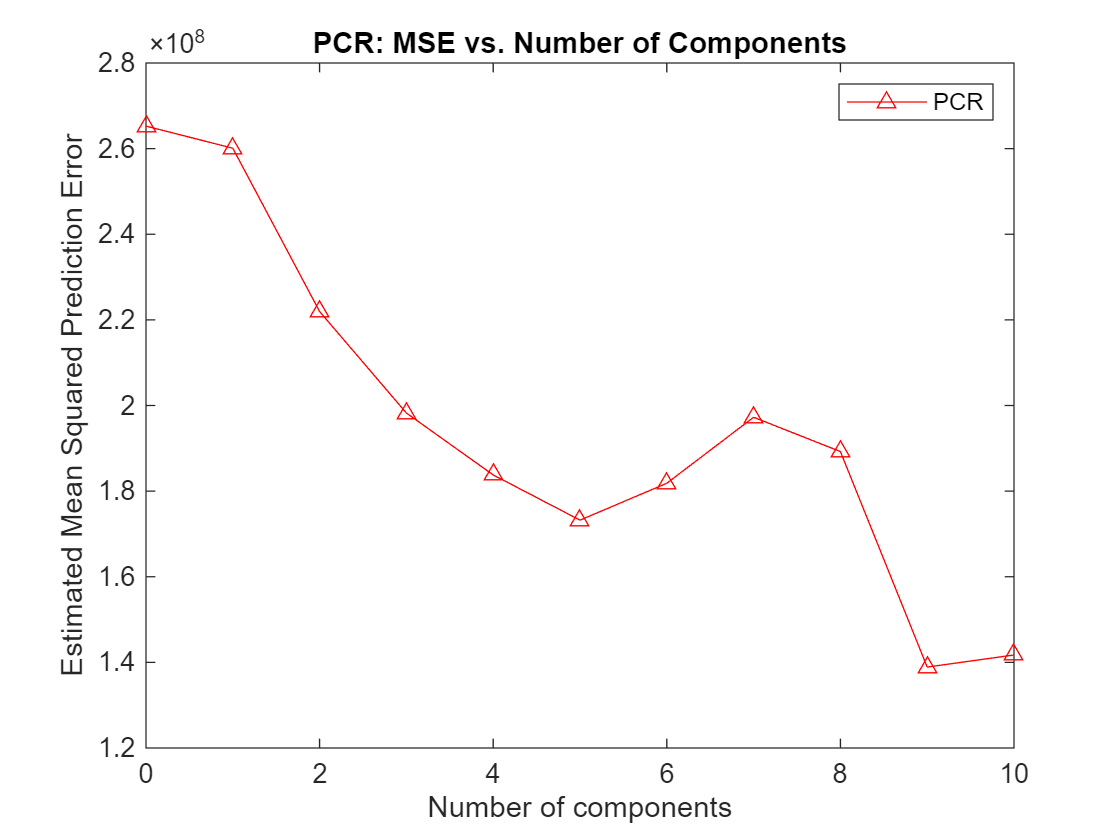

figure;
plot(0:p, PCRmsep, 'r-^');
xlabel('Number of components');
ylabel('Estimated Mean Squared Prediction Error');
legend('PCR');
title('PCR: MSE vs. Number of Components');

Retraining the model with optimal number of components (9 optimal, 5 local minima)

[coeff,scoreTrain,~,~,explained,mu] = pca(X_train);

scoreTrain9comp = scoreTrain(:,1:9);
final_PCR = fitlm(scoreTrain9comp,Y_train);

Evaluating final PCR model on test data

scoreTest9comp = (X_test-mu)*coeff(:,1:9);
ytest_predicted_PCR = predict(final_PCR,scoreTest9comp);
MSEtest_PCR = immse(Y_test,ytest_predicted_PCR)

MSEtest_PCR =    1.5488e+08


% Clear unused variables
clear n p PCRmsep scoreTest9comp scoreTrain9comp mu scoreTrain coeff

# Results & Discussion

## Model Comparison

% Compute RMSE for each model:
RMSE_linear = sqrt(MSE_linear)

RMSE_linear =         12598


RMSE_lasso = sqrt(MSEtest_lasso)

RMSE_lasso =         12696


RMSE_ridge = sqrt(MSEtest_ridge)

RMSE_ridge =         23099


RMSE_pcr = sqrt(MSEtest_PCR)

RMSE_pcr =         12445


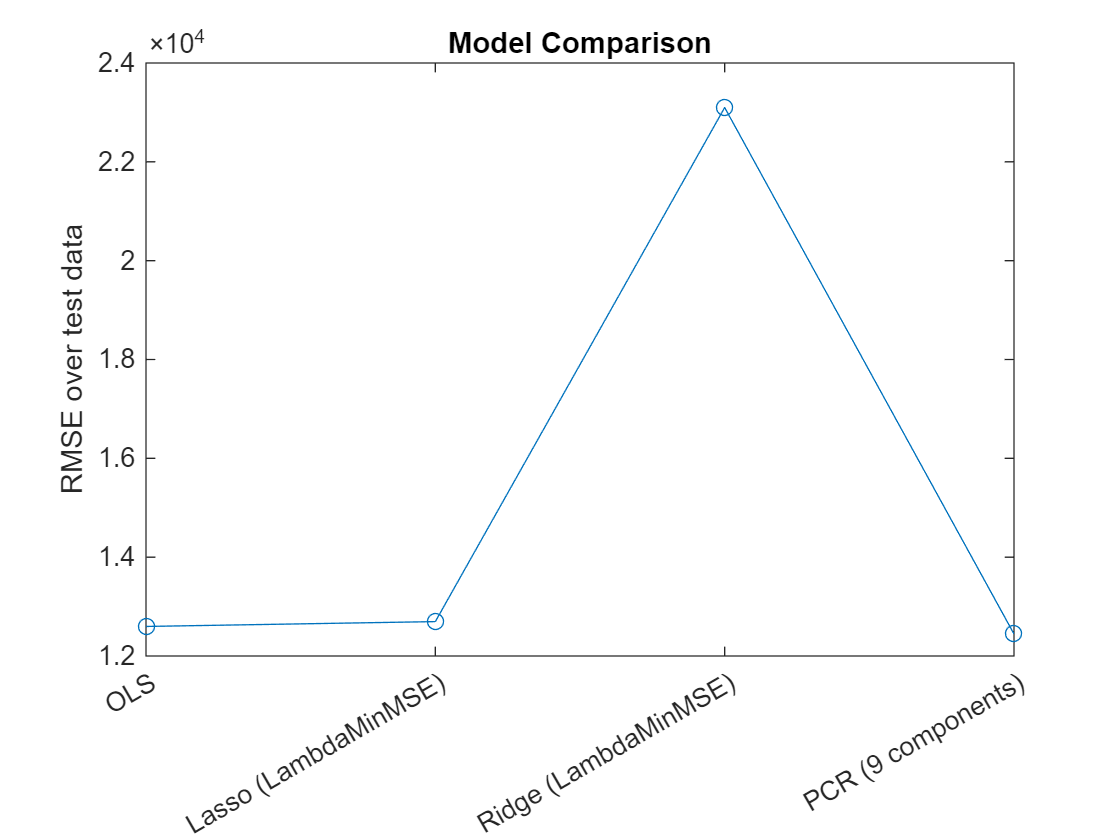


% Visualize the RMSEs:
all_errors = [RMSE_linear,RMSE_lasso,RMSE_ridge,RMSE_pcr];
model_names = {'OLS','Lasso (LambdaMinMSE)','Ridge (LambdaMinMSE)','PCR (9 components)'};

figure;
plot(all_errors,'-o');
set(gca, 'XTick', 1:length(model_names), 'XTickLabel', model_names);
title('Model Comparison')
ylabel('RMSE over test data');

Coefficients for linear and lasso

- Year

- Month

- Government cut (categorical: 1 no cuts, 2 cuts in effect (4/2024 onwards))

- Unemployment

- CPI (inflation)

- CCI (consumer confidence)

- Housing benefits paid (monthly total, EUR)

- Housing benefits paid per person (index, 4/2024 = 100) 

- Unemployment benefits paid (monthly, EUR)

- Unemployment benefits paid per person (index, 4/2024 = 100)

% Linear model:
linear_intercept = table2array(linear_mdl.Coefficients(1,1));
linear_coeffs = table2array(linear_mdl.Coefficients(2:end,1))';

% Lasso model:
lasso_intercept = fitInfofinal_lasso.Intercept;
lasso_coeffs = Bfinal_lasso';

% Summary table:
format short g

chosen_models = {'OLS','Lasso'};
var_names = {'YY','MM','Cut','Unempl.','CPI','CCI','HB MM','HB IDX','UB MM','UB IDX'};
metrics_table = table(...
    [linear_coeffs(1);lasso_coeffs(1)],...
    [linear_coeffs(2);lasso_coeffs(2)],...
    [linear_coeffs(3);lasso_coeffs(3)],...
    [linear_coeffs(4);lasso_coeffs(4)],...
    [linear_coeffs(5);lasso_coeffs(5)],...
    [linear_coeffs(6);lasso_coeffs(6)],...
    [linear_coeffs(7);lasso_coeffs(7)],...
    [linear_coeffs(8);lasso_coeffs(8)],...
    [linear_coeffs(9);lasso_coeffs(9)],...
    [linear_coeffs(10);lasso_coeffs(10)],...
    'VariableNames',var_names,...
    'RowNames',chosen_models)

metrics_table = 2×10 table
               YY         MM        Cut      Unempl.     CPI       CCI        HB MM      HB IDX        UB MM       UB IDX
             _______    _______    ______    _______    ______    ______    _________    _______    ___________    ______

    OLS       -14235      -2592     13890    8418.6     2544.1    470.25    0.0009082    -4162.4    -0.00036862    601.89
    Lasso    -3548.6    -1790.6    7633.2    4361.1          0    53.544            0    -874.08    -1.0093e-06         0
